% combine mask dataset generate

%% orig scene
load('init_test.mat', 'orig_bayer');
% load('init_test_8f.mat', 'orig_bayer');


%% init mask
% load
% init_mask = load('init_test.mat', 'mask_bayer');
% init_mask = load('init_test_8f.mat', 'mask_bayer');
% init_mask = init_mask.mask_bayer;
% img_num = size(init_mask,3);

% random generate
img_size = [512 512]; img_num=4;
% init_mask = gray_mask([img_size,img_num]); % uniform
init_mask = gray_mask([img_size,img_num], 'randn',[0.5 0.2]); % gaussian


%% combine matrix
% combine_matrix = eye(img_num); % non-combine
% 4 frame
% combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 0 1 0 1]; % combine1
combine_matrix =  [1 1 0 0; 0 1 1 0; 0 0 1 1; 1 1 0 1];% combine2
% combine_matrix = [1 0 1 0; 0 1 1 1; 0 0 1 1; 1 1 0 1]; % combine3
% combine_matrix = [1 0 1 1; 0 1 1 1; 0 0 1 1; 1 1 0 1]; % combine4
% combine_matrix = [0 1 1 1; 1 0 1 1; 1 1 0 1; 1 1 1 0]; % combine5
% combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 1 0 0 1]; % combine6 - Not full rank, rank=3
% combine_matrix = [1 1 1 0; 0 1 1 1; 1 0 1 1; 0 1 1 1]; % combine7 - Not full rank, rank=3, mask2=mask4
% combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 0 1 1 0]; % combine8 - Not full rank, rank=3, rank=3, mask2=mask4

% 8 frame
% random generation combine_matrix
% combine_matrix = single(binary_mask(img_num)); % combine1
% load combine_matrix
% load('combine_matrix_8f_1.mat', 'combine_matrix');
% load('combine_matrix_8f_2.mat', 'combine_matrix');
% load('combine_matrix_8f_3.mat', 'combine_matrix');

rank_combine_matrix = rank(combine_matrix)
mask_bayer = combine_mask(init_mask,combine_matrix);
% histgram
figure,hist(init_mask(:),10)
figure,hist(mask_bayer(:),10)
mean_mask_bayer1 = mean(mask_bayer,'a')
% [r,p,ar,ap] = matrix_corr(mask_bayer)



%% coding frame
coded_frame = single(mask_bayer).*single(orig_bayer);
meas_bayer = sum(coded_frame, 3);
mean_meas_bayer1 = mean(meas_bayer,'a')


%% normalize
% [mask_bayer, meas_bayer] = dvpdata_normalize(mask_bayer, meas_bayer);
% mask_max = max(mask_bayer,[],'a')
% mask_bayer = mask_bayer./ mask_max;
% meas_bayer = meas_bayer./ mask_max;
mean_mask_bayer2 = mean(mask_bayer,'a')
mean_meas_bayer2 = mean(meas_bayer,'a')


%% save dataset
save('test.mat','combine_matrix','init_mask','orig_bayer','mask_bayer','meas_bayer', '-v7.3')
% save('test_8f.mat','combine_matrix','init_mask','orig_bayer','mask_bayer','meas_bayer', '-v7.3')
% save('test.mat','orig_bayer','mask_bayer','meas_bayer','-v7.3')

% specialize random mask dataset generate
% flags
dl_cacti_flag = 0;
dvp_flag=1;

% params
img_num = 8;
% img_size = [512 512];
img_size = [256 256];

%% load orig
% orig = load('init_test.mat', 'orig_bayer')
% orig = load('traffic_bayer.mat', 'orig_bayer')
orig = load(['E:\project\CACTI\simulation\CI algorithm\PnP-SCI\' ...
    'dataset\simdata\zzh_data\traffic_bayer.mat'], 'orig_bayer')

orig = 包含以下字段的 struct :
    orig_bayer: [512×512×48 uint8]

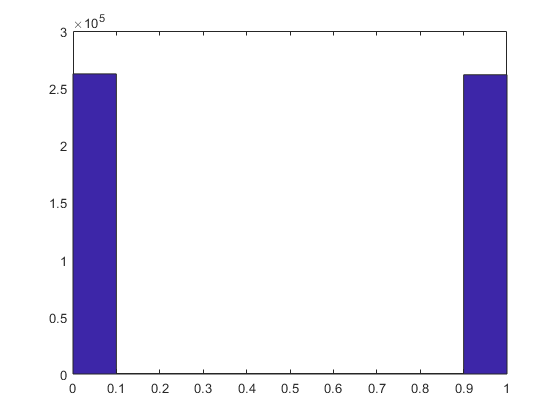

orig = orig.orig_bayer;
orig_bayer = orig(:,:,1:img_num);
if size(orig,1) ~= img_size(1)
    orig_bayer =imresize(orig_bayer, img_size);
end
% orig_bayer = orig_bayer/255;

%% mask
% load
% init_mask = load('init_test.mat', 'mask_bayer');
% init_mask = load('512scale_traffic_cacti_simu.mat', 'mask_bayer');
% init_mask = load('mask.mat', 'mask');
% init_mask = init_mask.mask;
% mask_bayer = init_mask(:,:,1:img_num);

% generate
% mask_bayer = gray_mask([img_size,img_num]);
mask_bayer = single(binary_mask([img_size,img_num]));

figure,hist(mask_bayer(:),10)

mean_mask_bayer1 = mean(mask_bayer,'a')

mean_mask_bayer1 = single
0.4993



%% coding frame
coded_frame = single(mask_bayer).*single(orig_bayer);
meas_bayer = sum(coded_frame, 3);


%% normalize
% [mask_bayer, meas_bayer] = dvpdata_normalize(mask_bayer, meas_bayer);
% mask_max = max(mask_bayer,[],'a')
% mask_bayer = mask_bayer./ mask_max;
% meas_bayer = meas_bayer./ mask_max;
figure,hist(mask_bayer(:),10)

mean_mask_bayer2 = mean(mask_bayer,'a')

mean_mask_bayer2 = single
0.4993

mean_meas_bayer2 = mean(meas_bayer,'a')

mean_meas_bayer2 = single
463.7370


if dvp_flag
    % save dataset for dvp
%     dataset_dir = './'
    dataset_dir = 'E:\project\CACTI\simulation\CI algorithm\PnP-SCI\dataset\simdata\zzh_data\'
%     dataset_dir = 'E:\project\CACTI\simulation\CI algorithm\dvp\dvp_inv\dataset\'
    dataset_name = 'test.mat';
    save([dataset_dir dataset_name],'orig_bayer','mask_bayer','meas_bayer','-v7.3')
end

dataset_dir = 'E:\project\CACTI\simulation\CI algorithm\PnP-SCI\dataset\simdata\zzh_data\'


if dl_cacti_flag
    %% save dataset for dl_cacti
    % meas = meas_bayer/max(meas_bayer,[],'a')*255;
    meas = meas_bayer;
    mask = mask_bayer;
    % validation
    mean_mask = mean(mask,'a')
    mean_meas = mean(meas,'a')
    max_meas = max(meas,[],'a')
    %  dataset_dir = './'
    dataset_dir = 'E:\project\CACTI\simulation\CI algorithm\DL-CACTI\dataset\';
    mask_name = ['mask_rescale_512scale_traffic_syn_cr_' num2str(img_num) '.mat'];
    meas_name = ['meas_rescale_512scale_traffic_syn_cr_' num2str(img_num) '.mat'];
    save([dataset_dir mask_name], 'mask')
    save([dataset_dir meas_name], 'meas')
end

% reconstruction data processing
save('gapfastdvdnet_test4_sigma12_combine1.mat','combine_matrix','init_mask','orig_bayer','mask_bayer','meas_bayer', '-append')
% mean(orig_bayer./max(orig_bayer,[],'a'),'a')

% data feature parameter evaluation
% orig_bayer
min_orig_bayer = min(orig_bayer,[],'all')
mean_orig_bayer = mean(orig_bayer,'a')
max_orig_bayer = max(orig_bayer,[],'all')

% init_mask
% min_init_mask_bayer = min(init_mask,[],'all')
% mean_init_mask_bayer = mean(init_mask,'a')
% max_init_mask_bayer = max(init_mask,[],'all')
% [r,p,ar,ap] = matrix_corr(init_mask)
% figure,hist(mask_bayer(:),10)

% mask_bayer
min_mask_bayer = min(mask_bayer,[],'all')
mean_mask_bayer = mean(mask_bayer,'a')
max_mask_bayer = max(mask_bayer,[],'all')
figure,hist(mask_bayer(:),10)
% [r,p,ar,ap] = matrix_corr(mask_bayer)

% meas_bayer
min_meas_bayer = min(meas_bayer,[],'all')
mean_meas_bayer = mean(meas_bayer,'a')
max_meas_bayer = max(meas_bayer,[],'all')
% [r,p,ar,ap] = matrix_corr(mask_bayer)

% cacti